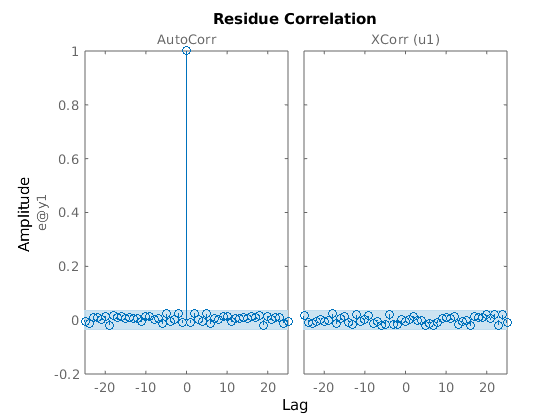

f_data = load("dataG0arx.mat");
u = f_data.u;
y = f_data.y;
data = iddata(y,u,1);
na = 4;
nb = 2;
nk = 3;
sys_arx = arx(data,[na nb nk]);
resid(sys_arx,data)

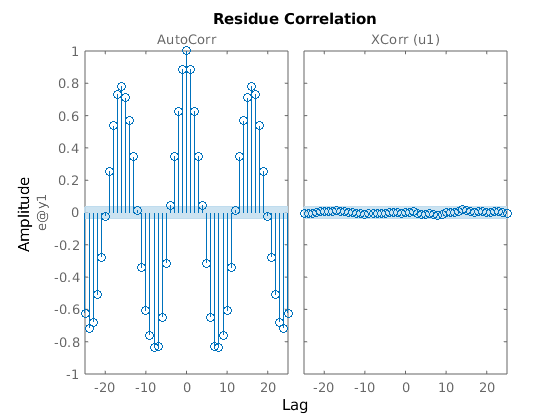

sys_oe = oe(data,[nb, na, nk]);
resid(sys_oe,data)

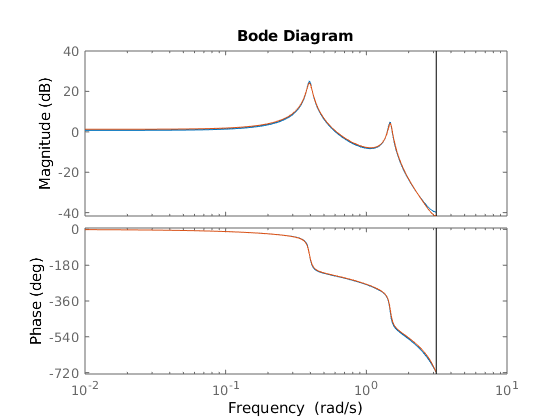

G0_arx = tf(sys_arx.B,sys_arx.A,1);
H0_arx = tf(1,sys_arx.A,1);
G0_oe = tf(sys_oe.B,sys_oe.F,1);
bode(G0_arx,G0_oe)

## Problem 4

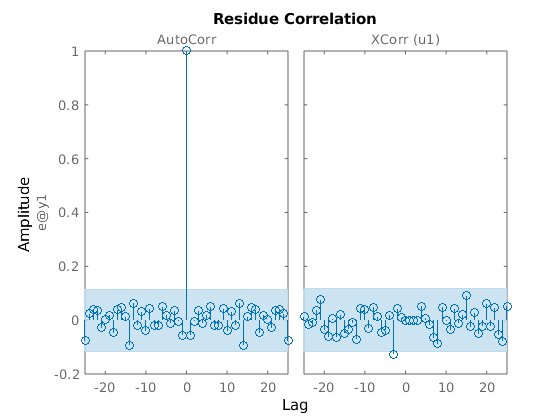

G0 = tf([1 -0.5 0.2 0.8 0.1],[1 -1.7 1.6 -0.8 0.25],1);
H0 = tf([1 0 0 0 0],[1 -1.7 1.6 -0.8 0.25],1);
N = 500;
e = randn(N,1);
u = randn(N,1);
y = lsim(G0,u)+lsim(H0,e);
data = iddata(y,u,1);
na = 4;
nb = 4;
nk = 0;
sys_arx = arx(data,[na nb nk]);
figure();
resid(sys_arx,data)

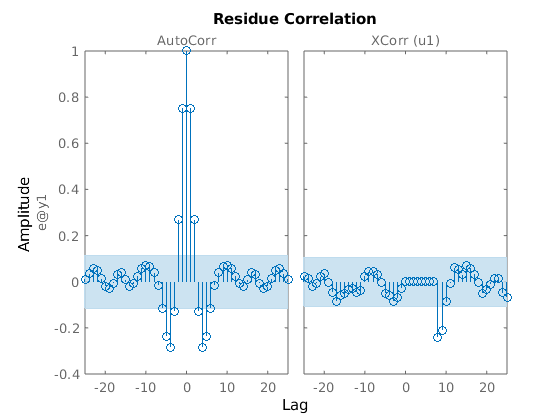

nb = 8;
nk = 0;
figure();
sys_fir = arx(data,[0 nb nk]);
resid(sys_fir,data)